Hydraulic variables

Rh = 0.1; %Resistance
Ch = 0.1; %Compliance
Brake_factor = 1000;

Vehicle variables

mv = 1200; %Vehicle mass (kg)
Rw = 0.28; %Wheel radius (m)
g = 9.81; %Gravity (m/s^2)
I = 0.01; %Moment of inertia (kg*m^2)
v0 = 28; %Vehicle initiale speed (m/s)
Tbmax = 2000; %Max braking torque (N*m)

Mu-slip variables

A = 0.9;
B = 1.07;
C = 0.2773;
D = 0.0026;

Plots from the Simulink model

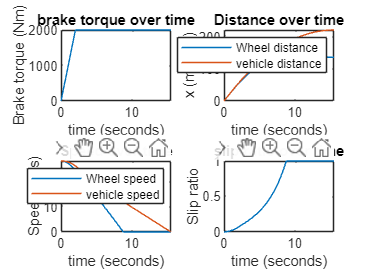

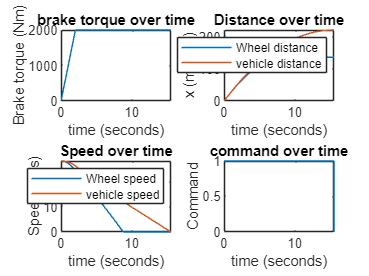

subplot(2, 2, 1);
time = out.tout;
brake_torque = out.brake_torque.signals.values;
plot(time, brake_torque)
title('brake torque over time')
xlabel('time (seconds)')
ylabel('Brake torque (Nm)')

subplot(2, 2, 2);
time = out.tout;
distance1 = out.Distance.signals(1).values;
distance2 = out.Distance.signals(2).values;
plot(time, distance1, time, distance2)
title('Distance over time')
xlabel('time (seconds)')
ylabel('x (meters)')
legend('Wheel distance','vehicle distance')

subplot(2, 2, 3);
time = out.tout;
speed1 = out.Speed.signals(2).values;
speed2 = out.Speed.signals(1).values;
plot(time, speed1, time, speed2)
title('Speed over time')
xlabel('time (seconds)')
ylabel('Speed (m/s)')
legend('Wheel speed','vehicle speed')

subplot(2, 2, 4);
time = out.tout;
slip = out.Slip.signals.values;
plot(time, slip)
title('slip ratio over time')
xlabel('time (seconds)')
ylabel('Slip ratio')